rng(0)

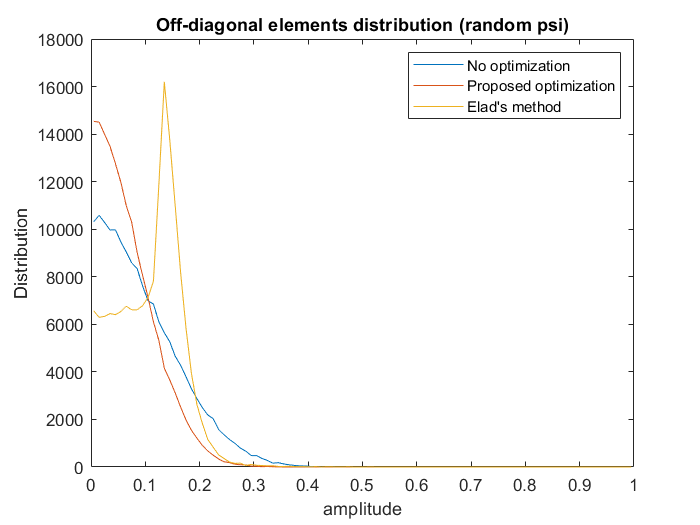


% D_initial = normrnd(0,1,100,200);
% phi = optimise_completeDic(D_initial,eye(200,200),60,0.02);

phi = normrnd(0,1,100,200);
psi = normrnd(0,1,200,400);
phi_optimised = optimise_completeDic(phi*psi,psi,60,0.02);
%phi_optimised = optimise_incompleteDic(phi,psi,60,0.02);
phi_elad = elad_fixed(psi,0.25,size(phi,1),0.5,60);

%figure 1(a)
figure;
my_hist(off_diag_gram(phi*psi));   
hold on;
my_hist(off_diag_gram(phi_optimised*psi));
hold on;
my_hist(off_diag_gram(phi_elad*psi));   
hold off;
xlabel("amplitude")
ylabel("Distribution")
title("Off-diagonal elements distribution (random psi)")
legend("No optimization","Proposed optimization","Elad's method")

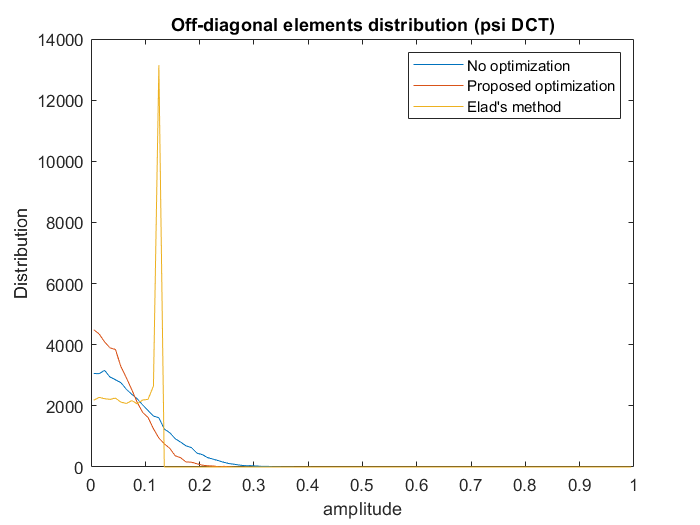


phi = normrnd(0,1,100,200);
psi = dctmtx(200);
phi_optimised = optimise_completeDic(phi,psi,60,0.02);
phi_elad = elad_fixed(psi,0.25,size(phi,1),0.5,60);

%figure 1(b)
figure;
my_hist(off_diag_gram(phi*psi));
hold on;
my_hist(off_diag_gram(phi_optimised*psi));
hold on;
my_hist(off_diag_gram(phi_elad*psi));
hold off;
xlabel("amplitude")
ylabel("Distribution")
title("Off-diagonal elements distribution (psi DCT)")
legend("No optimization","Proposed optimization","Elad's method")

%figure 2(b) OMP
P = [20:5:80];
n=120;
psi = dctmtx(n);

error_rate_unopt_omp = zeros(length(P),1);
error_rate_opt_omp = zeros(length(P),1);
error_rate_elad_omp = zeros(length(P),1);
for ii = [1:length(P)]
    p = P(ii);
    s=8;
    phi = normrnd(0,1,p,n);
    phi_optimised = optimise_completeDic(phi*psi,psi,150,0.01);
    phi_elad = elad_relative(psi,20,size(phi,1),0.95,1000);
    
    error_unopt = 0;
    error_opt = 0;
    error_elad = 0;
    
    J = 1000;
    for jj = [1:J]
        %display(jj);
        alpha = zeros(n,1);
        alpha(randperm(n,s)) = 100*rand(s,1);
        omp_epsilon = 0.1;
        alpha_reconstructed_unopt = omp(phi*psi*alpha,phi*psi,omp_epsilon);
        error_unopt = error_unopt + norm(alpha - alpha_reconstructed_unopt)/norm(alpha);
        
        alpha_reconstructed_opt = omp(phi_optimised*psi*alpha,phi_optimised*psi,omp_epsilon);
        error_opt = error_opt + norm(alpha - alpha_reconstructed_opt)/norm(alpha);
        
        alpha_reconstructed_elad = omp(phi_elad*psi*alpha,phi_elad*psi,omp_epsilon);
        error_elad = error_elad + norm(alpha - alpha_reconstructed_elad)/norm(alpha);
    end
    error_rate_unopt_omp(ii) = error_unopt/J;
    error_rate_opt_omp(ii) = error_opt/J;
    error_rate_elad_omp(ii) = error_elad/J;
end

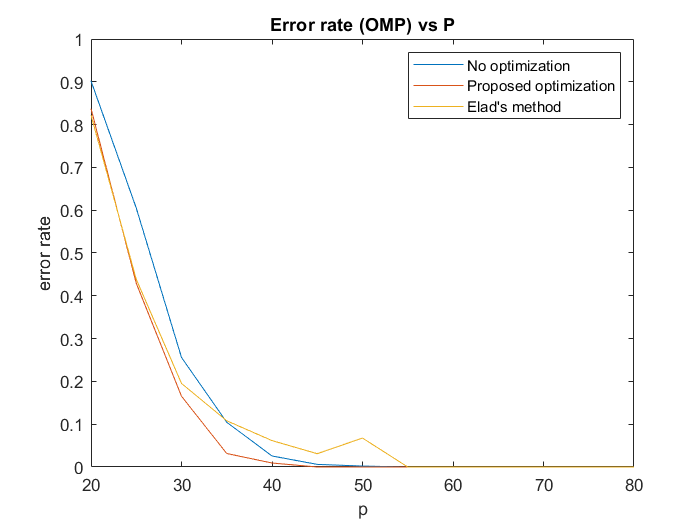

%figure 2(b) OMP
figure;
plot(P,error_rate_unopt_omp)
hold on;
plot(P,error_rate_opt_omp)
hold on;
plot(P,error_rate_elad_omp)
hold off;
xlabel("p")
ylabel("error rate")
title("Error rate (OMP) vs P")
legend("No optimization","Proposed optimization","Elad's method")

%figure 2(c) BP
P = [20:5:80];
n=120;
psi = dctmtx(n);

error_rate_unopt_bp = zeros(length(P),1);
error_rate_opt_bp = zeros(length(P),1);
error_rate_elad_bp = zeros(length(P),1);
for ii = [1:length(P)]
    p = P(ii);
    s=8;
    phi = normrnd(0,1,p,n);
    phi_optimised = optimise_completeDic(phi*psi,psi,150,0.01);
    phi_elad = elad_relative(psi,20,size(phi,1),0.95,1000);
    
    error_unopt = 0;
    error_opt = 0;
    error_elad = 0;
    
    J = 1000;
    for jj = [1:J]
        %display(jj);
        alpha = zeros(n,1);
        alpha(randperm(n,s)) = 100*rand(s,1);
        
        alpha_reconstructed_unopt = bp(phi*psi*alpha,phi*psi);
        error_unopt = error_unopt + norm(alpha - alpha_reconstructed_unopt)/norm(alpha);
        
        alpha_reconstructed_opt = bp(phi_optimised*psi*alpha,phi_optimised*psi);
        error_opt = error_opt + norm(alpha - alpha_reconstructed_opt)/norm(alpha);
        
        alpha_reconstructed_elad = bp(phi_elad*psi*alpha,phi_elad*psi);
        error_elad = error_elad + norm(alpha - alpha_reconstructed_elad)/norm(alpha);
    end
    error_rate_unopt_bp(ii) = error_unopt/J;
    error_rate_opt_bp(ii) = error_opt/J;
    error_rate_elad_bp(ii) = error_elad/J;
end

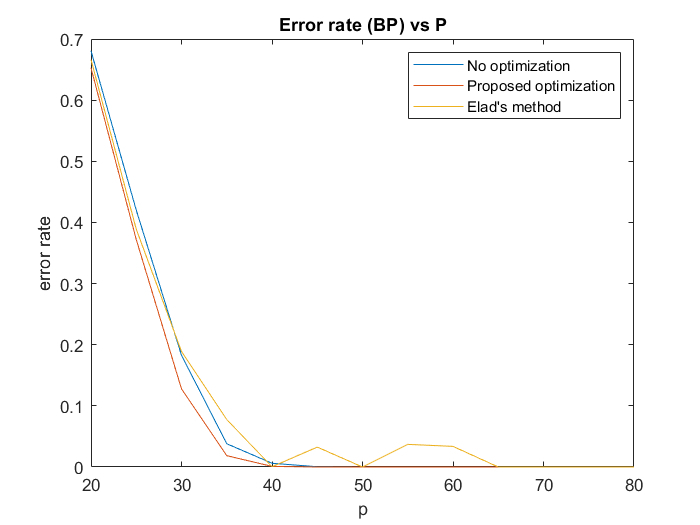

%figure 2(c) BP
figure;
plot(P,error_rate_unopt_bp)
hold on;
plot(P,error_rate_opt_bp)
hold on;
plot(P,error_rate_elad_bp)
hold off;
xlabel("p")
ylabel("error rate")
title("Error rate (BP) vs P")
legend("No optimization","Proposed optimization","Elad's method")

%figure 3(a) BP
S = [1:20];
n=120;
psi = dctmtx(n);

Error_rate_unopt_bp = zeros(length(S),1);
Error_rate_opt_bp = zeros(length(S),1);
Error_rate_elad_bp = zeros(length(S),1);
for ii = [1:length(S)]
    p = 30;
    s = S(ii);
    phi = normrnd(0,1,p,n);
    phi_optimised = optimise_completeDic(phi*psi,psi,150,0.01);
    phi_elad = elad_relative(psi,20,size(phi,1),0.95,1000);
    
    error_unopt = 0;
    error_opt = 0;
    error_elad = 0;
    
    J = 1000;
    for jj = [1:J]
        %display(jj);
        alpha = zeros(n,1);
        alpha(randperm(n,s)) = 100*rand(s,1);
        
        alpha_reconstructed_unopt = bp(phi*psi*alpha,phi*psi);
        error_unopt = error_unopt + norm(alpha - alpha_reconstructed_unopt)/norm(alpha);
        
        alpha_reconstructed_opt = bp(phi_optimised*psi*alpha,phi_optimised*psi);
        error_opt = error_opt + norm(alpha - alpha_reconstructed_opt)/norm(alpha);
        
        alpha_reconstructed_elad = bp(phi_elad*psi*alpha,phi_elad*psi);
        error_elad = error_elad + norm(alpha - alpha_reconstructed_elad)/norm(alpha);
    end
    Error_rate_unopt_bp(ii) = error_unopt/J;
    Error_rate_opt_bp(ii) = error_opt/J;
    Error_rate_elad_bp(ii) = error_elad/J;
end

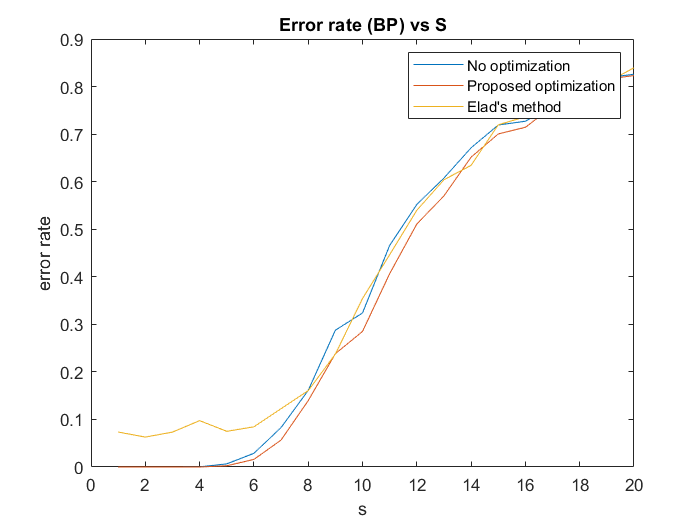

%figure 3(a) BP
figure;
plot(S,Error_rate_unopt_bp)
hold on;
plot(S,Error_rate_opt_bp)
hold on;
plot(S,Error_rate_elad_bp)
hold off;
xlabel("s")
ylabel("error rate")
title("Error rate (BP) vs S")
legend("No optimization","Proposed optimization","Elad's method") 

%figure 3(b) OMP
S = [1:20];
n=120;
psi = dctmtx(n);

Error_rate_unopt_omp = zeros(length(S),1);
Error_rate_opt_omp = zeros(length(S),1);
Error_rate_elad_omp = zeros(length(S),1);
for ii = [1:length(S)]
    p = 30;
    s = S(ii);
    phi = normrnd(0,1,p,n);
    phi_optimised = optimise_completeDic(phi*psi,psi,150,0.01);
    phi_elad = elad_relative(psi,20,size(phi,1),0.95,1000);
    
    error_unopt = 0;
    error_opt = 0;
    error_elad = 0;
    
    J = 1000;
    for jj = [1:J]
        %display(jj);
        alpha = zeros(n,1);
        alpha(randperm(n,s)) = 100*rand(s,1);
        
        alpha_reconstructed_unopt = bp(phi*psi*alpha,phi*psi);
        error_unopt = error_unopt + norm(alpha - alpha_reconstructed_unopt)/norm(alpha);
        
        alpha_reconstructed_opt = bp(phi_optimised*psi*alpha,phi_optimised*psi);
        error_opt = error_opt + norm(alpha - alpha_reconstructed_opt)/norm(alpha);
        
        alpha_reconstructed_elad = bp(phi_elad*psi*alpha,phi_elad*psi);
        error_elad = error_elad + norm(alpha - alpha_reconstructed_elad)/norm(alpha);
    end
    Error_rate_unopt_omp(ii) = error_unopt/J;
    Error_rate_opt_omp(ii) = error_opt/J;
    Error_rate_elad_omp(ii) = error_elad/J;
end

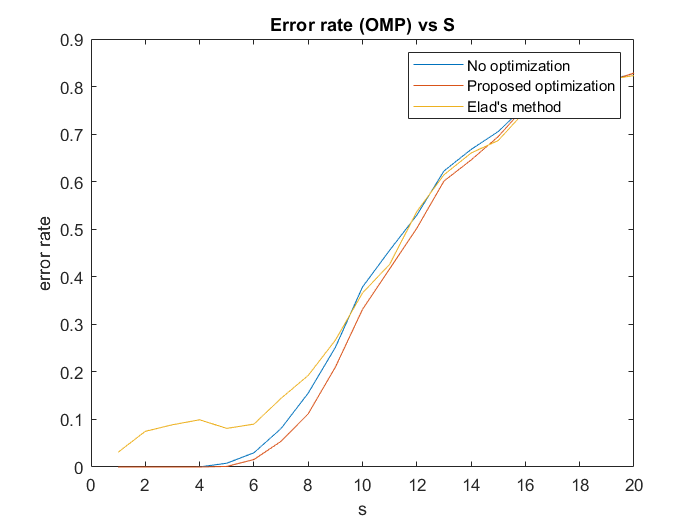

%figure 3(b) OMP
figure;
plot(S,Error_rate_unopt_omp)
hold on;
plot(S,Error_rate_opt_omp)
hold on;
plot(S,Error_rate_elad_omp)
hold off;
xlabel("s")
ylabel("error rate")
title("Error rate (OMP) vs S")
legend("No optimization","Proposed optimization","Elad's method") 

function output = optimise_completeDic(D,psi,K,eta)
    for k = 1:K
        Y = normc(D);
        D = Y - eta*(Y)*(((Y')*Y)-eye(size(Y,2)));
    end
    output = D*(pinv(psi));
end

function output = optimise_incompleteDic(phi,psi,K,eta)
    for k = 1:K
        D = (phi*psi);
        phi = D*pinv(psi) - eta*(D)*(((D')*D)-eye(size(psi,2)))*(psi');
    end
    output = phi;
end

function output = elad_fixed(psi,t,p,gamma,iter)
    P = rand(p,size(psi,1));
    pinv_psi = pinv(psi);
    for ii = 1:iter
        D = normc(P*psi);
        G = D'*D;
        G_new = G;
        G_new(abs(G)>=t & ~eye(size(G))) = gamma*G(abs(G)>=t & ~eye(size(G)));
        G_new(abs(G)>=gamma*t & abs(G)<t & ~eye(size(G))) = gamma*t*sign(G(abs(G)>=gamma*t & abs(G)<t & ~eye(size(G))));
        [~,E,V] = svd(G_new);
        S = sqrt(E(1:p,1:p))*(V(:,1:p))';
        P = S*pinv_psi;
    end
    output = P;
end

function output = elad_relative(psi,t,p,gamma,iter)
    P = rand(p,size(psi,1));
    pinv_psi = pinv(psi);
    index = ceil((t/100)*(size(psi,2)^2));
    for ii = 1:iter
        D = normc(P*psi);
        G = D'*D;
        
        tmp = sort(abs(G(~eye(size(G)))),'descend');
        t = tmp(index);
        
        G_new = G;
        G_new(abs(G)>=t & ~eye(size(G))) = gamma*G(abs(G)>=t & ~eye(size(G)));
        G_new(abs(G)>=gamma*t & abs(G)<t & ~eye(size(G))) = gamma*t*sign(G(abs(G)>=gamma*t & abs(G)<t & ~eye(size(G))));
        [~,E,V] = svd(G_new);
        S = sqrt(E(1:p,1:p))*(V(:,1:p))';
        P = S*pinv_psi;
    end
    output = P;
end

function output = omp(y,A,epsilon)
    r = y;
    [m,n] = size(A);
    theta = zeros(n,1);
    T = zeros(m,1);
    for i = [1:m]
        if norm(r) < epsilon
            break
        end
        [~,j] = max(abs((r')*normc(A)));
        T(i) = j;
        theta(T(1:i)) = pinv(A(:,T(1:i)))*y;
        r = y - A(:,T(1:i))*theta(T(1:i));
    end
    output = theta;
end

function output = bp(y,A)
    B = [A,-A];
    options = optimoptions('linprog','Display','none');
    tmp = linprog(ones(size(B,2),1),[],[],B,y,zeros(size(B,2),1),[],options);
    output = tmp(1:end/2) - tmp((end/2) + 1: end);
end

function x = off_diag_gram(D)
    Y = normc(D);
    B = (Y')*(Y) - eye(size(Y,2));
    x = abs(B(~eye(size(B))));
end

function my_hist(x)
    [values,edges] = histcounts(x,[0:100]/100);
    plot((edges(1:end-1)+edges(2:end))/2, values);
    xlabel('value');
    ylabel('Frequency');
    return
end
